clear; close; clc;
%flight condtion for cruise
load('CARTRIDGE_105_MILLIMETER_HERA_M927.mat')

%d = CARTRIDGE_105_MILLIMETER_HERA_M927.Hydrolic_Diameter;
%l = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length;
       

%S_ref = pi*d/4;
%Weight_50 = (CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Mass - CARTRIDGE_105_MILLIMETER_HERA_M927.Propellant_Mass/2) * 9.81; % wieght at 50% fuel load
%Lift = Weight_50;

isCoasting = true; % we are doing both true and false (this should not be defined here)

%height = 1000; % we will do this for various altitudes. not yet implemented
height = 0; % we will do this for various altitudes. not yet implemented


% dimentions that match fleeman graph
% for debugging
S_ref = convlength(convlength(2,"ft","m"),"ft","m") % convert ft^2 to m^2

S_ref = 0.1858

d = 4 * S_ref / pi;
d_noseTip = 0; % assumption
d_bt = d; % assumption
l = 10 * d;
l_N = l * 3/10; % assumption
A_nE = 0; % assumption
Weight_50 = convforce(2000,"lbf","N");
Lift = Weight_50;






% we will compute velocity from the qbar as qbar is our independent
% variable
% %for various velocities (varying q_bar)
% Vmin = 100; Vmax = 680; %m/s
% Vstep = 1; %m/s

%V_list = Vmin:Vstep:Vmax % velocity range
%Vsteps = length(V_list);

% initialize looop solution arrays
nPoints = 100 % 1000 is a good number

nPoints = 100


%q_bars = logspace(2,4,nPoints) * 47.880259; % logspace in lb/ft^2 to Pa
q_bars = linspace(10^2,10^4,nPoints) * 47.880259; % linspace in lb/ft^2 to Pa

alpha_optimum = zeros(nPoints,0);
V_list = zeros(nPoints,0);


L_over_D_1g = zeros(nPoints,0);
L_over_D_1g_powered = zeros(nPoints,0);

syms alpha

for j = 1:nPoints
    q = q_bars(j);

    [~,a,~,rho] = atmosisa(height);
    V = sqrt(2*q/rho);
    V_list(j) = V;
    M = V/a;
    
    C_L = Lift/(S_ref*q);
    %C_L = Weight_50/(q*S_ref)
    
    %newton raphson to converge on the optimal value for alpha for lift=weight
%     alpha_guess = .001;
%     for i = 1:10000
%         C_N = normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_guess);
%         C_N_alpha = normalForce_withRespectTo_alpha(d/2,d/2,0);
%         alpha_new = alpha_guess - (C_N-C_L)/C_N_alpha; % havent used the deriviative here
%         if abs(alpha_new - alpha_guess) < .0001 % we have sufficiently converged (.001 rad - 0.0573 deg)
%             break % no need to futher itterate
%         end
%     end

    %VPA solve for alpha
    assume(alpha > 0)
    assumeAlso(alpha < deg2rad(15))
    % there are probably at least two possible alphas
    %alpha_guess =
    %double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, .0001)); % this will gereate worse results
    alpha_guess = double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, deg2rad(15)));
    

    alpha_optimum(j) = alpha_guess;

%     L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), ...
%         dragCoeff_zeroLift_body(M,q,CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length,d,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area,isCoasting), ...
%         alpha_optimum(j));

    L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), ...
        dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_nE, isCoasting), ...
        alpha_optimum(j));

    % only impact of thrust is here (there seems to be no impact on L/D)
    L_over_D_1g_powered(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_nE, isCoasting), alpha_optimum(j));
end

%cruise_results = {alpha_optimum, L_over_D_1g, L_over_D_1g_powered, q_bars} % as cell array
cruise_result.alpha_optimum = alpha_optimum;
cruise_result.alpha_optimum = q_bars;
cruise_result.L_over_D_1g = L_over_D_1g;
cruise_result.L_over_D_1g_powered = L_over_D_1g_powered;
cruise_result.alt = height;
%cruise_results = {cruise_result} % something like this to madd my results
%to the cell array

alpha_optimum

alpha_optimum =     1.1153    0.6482    0.4891    0.4031    0.3476    0.3080    0.2782    0.2546    0.2354    0.2193    0.2057    0.1940    0.1837    0.1747    0.1666    0.1594    0.1528    0.1469    0.1414    0.1364    0.1318    0.1276    0.1236    0.1199    0.1164    0.1132    0.1102    0.1073    0.1046    0.1020    0.0996    0.0973    0.0951    0.0931    0.0911    0.0892    0.0874    0.0857    0.0840    0.0824    0.0809    0.0794    0.0780    0.0767    0.0754    0.0741    0.0729    0.0717    0.0706    0.0695


L_over_D_1g

L_over_D_1g =     0.4684    1.2180    1.6318    1.8896    2.0403    2.1120    2.1253    2.0966    2.0389    1.9622    1.8741    1.7803    1.6846    1.5899    1.0340    1.0157    0.9976    0.9798    0.9623    0.9453    0.9287    0.9126    0.8969    0.8818    0.8671    0.8528    0.8390    0.8256    0.8127    0.8002    0.7880    0.7762    0.7648    0.7537    0.7430    0.7326    0.7225    0.7127    0.7031    0.6939    0.6849    0.6761    0.6676    0.6594    0.6513    0.6435    0.6358    0.6284    0.6211    0.6140


L_over_D_1g_powered

L_over_D_1g_powered =     0.4684    1.2180    1.6318    1.8896    2.0403    2.1120    2.1253    2.0966    2.0389    1.9622    1.8741    1.7803    1.6846    1.5899    1.0340    1.0157    0.9976    0.9798    0.9623    0.9453    0.9287    0.9126    0.8969    0.8818    0.8671    0.8528    0.8390    0.8256    0.8127    0.8002    0.7880    0.7762    0.7648    0.7537    0.7430    0.7326    0.7225    0.7127    0.7031    0.6939    0.6849    0.6761    0.6676    0.6594    0.6513    0.6435    0.6358    0.6284    0.6211    0.6140


q_bars

q_bars = 1.0e+05 *

    0.0479    0.0958    0.1436    0.1915    0.2394    0.2873    0.3352    0.3830    0.4309    0.4788    0.5267    0.5746    0.6224    0.6703    0.7182    0.7661    0.8140    0.8618    0.9097    0.9576    1.0055    1.0534    1.1012    1.1491    1.1970    1.2449    1.2928    1.3406    1.3885    1.4364    1.4843    1.5322    1.5800    1.6279    1.6758    1.7237    1.7716    1.8194    1.8673    1.9152    1.9631    2.0110    2.0589    2.1067    2.1546    2.2025    2.2504    2.2983    2.3461    2.3940


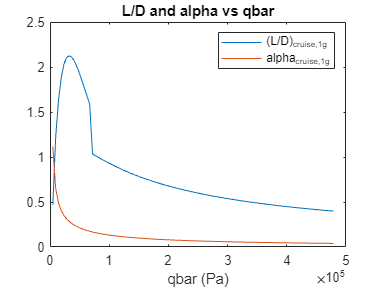


% plot trend of l/d and alpha
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

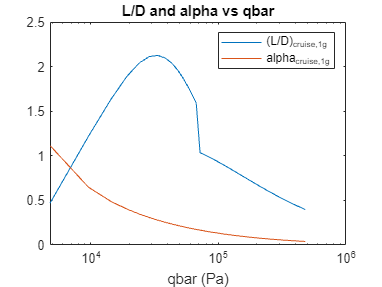

semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

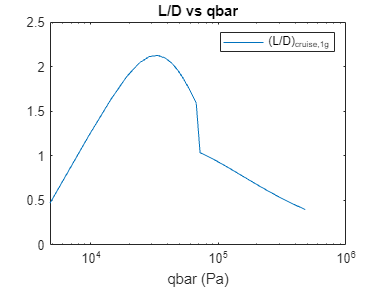


semilogx(q_bars,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}"]);

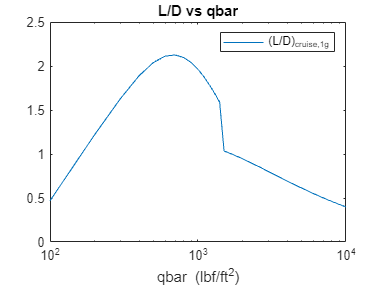

%to match fleeman
semilogx(q_bars/47.880259,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (lbf/ft^2)"); legend(["(L/D)_{cruise,1g}"]);

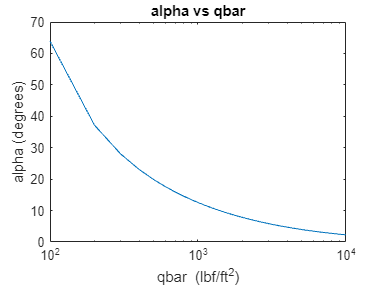


%alpha vs qbar
semilogx(q_bars/47.880259,rad2deg(alpha_optimum)); title("alpha vs qbar"); xlabel("qbar (lbf/ft^2)"); ylabel("alpha (degrees)");

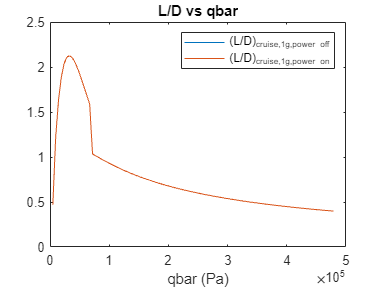


%compare powered and unpowerd
plot(q_bars,[L_over_D_1g; L_over_D_1g_powered]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g,power off}", "(L/D)_{cruise,1g,power on}"]); % this plot is unintresting as drag reduction is negligeable